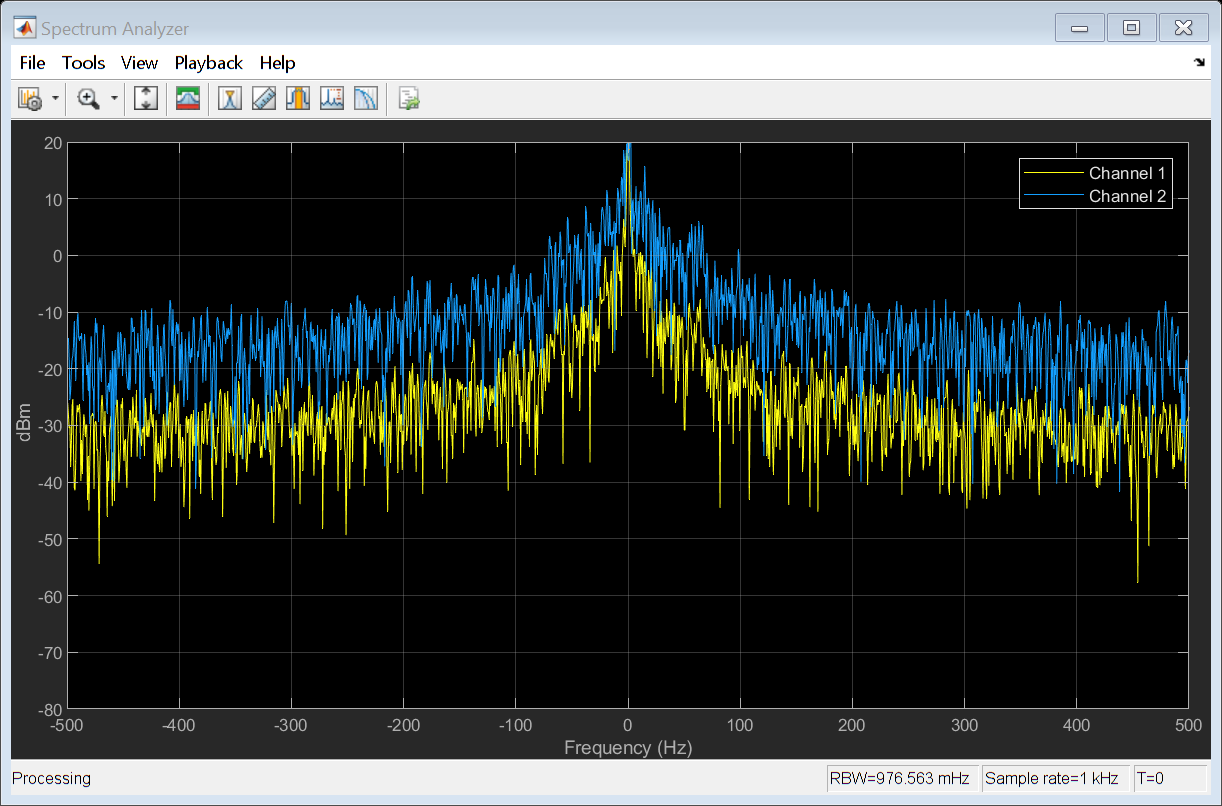

fs = 1e3;  % Sample rate (Hz)
ts = 1/fs; % Sample period (s)
fd = 10;   % Frequency deviation (Hz)
t = (0:ts:5-ts)';
x = wgn(length(t),1,0);
fmmod1 = comm.FMModulator( ...
    'SampleRate',fs, ...
    'FrequencyDeviation',fd);
fmmod2 = comm.FMModulator( ...
    'SampleRate',fs, ...
    'FrequencyDeviation',5*fd);
y1 = fmmod1(x);
y2 = fmmod2(x);
specanalyzer = dsp.SpectrumAnalyzer('SampleRate',fs,'ShowLegend',true);
specanalyzer([y1 y2])